STA = [];
for i=1:22
    i
    fs = blwgn_meta_struct(i).moth.fs;
    try
        STA = [STA; blwgn_meta_struct(i).moth.STA];
    catch 
        continue;
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

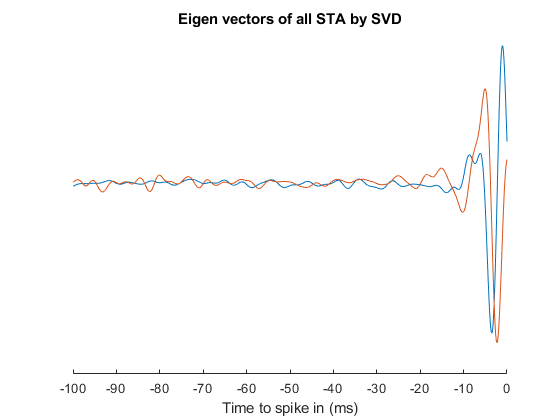

ax =   Axes (Eigen vectors of all STA by SVD) with properties:

             XLim: [-100 0]
             YLim: [-0.2500 0.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


[U,S,W] = svd(STA, 'econ');

figure;
t = linspace(-100,0,size(STA,2));
plot(t, W(:,1:2))
box off
xlabel('Time to spike in (ms)');
title('Eigen vectors of all STA by SVD')
ax = gca;
ax.YAxis.Visible = 'off'

figure;
plot(W(:,2)); hold on;
plot(diff(W(:,1)));